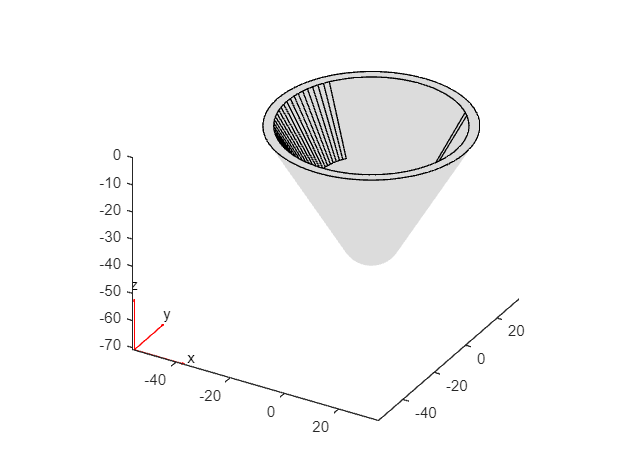

figure
gm= importGeometry(".\models\Cone70 v1.stl"); % input
target_angle = 60;          % determining target angle for complex shapes
preform_angle = 40;         % input
start_point = [-31.1769145362 0 0];
pdegplot(gm)

### Selecting the inside surface

[T,~,~,~] = stlread(".\models\Cone70 v1.stl");   % T contains list of vertices and the facets
pointsPerFacet = 100;          %input
inside_facets = 0;
face_normals = faceNormal(T);

for i = 1:size(face_normals,1)
    normal = face_normals(i,3);
    if(normal) > 0
        inside_facets = inside_facets+1;
    end
end

total_pts = pointsPerFacet*inside_facets;


### Method-1 : Z-shift

pntcld = zeros(total_pts,3);  %initial point cloud
pntcld2 = zeros(total_pts,3); %preform point cloud
p = 0;

for i = 1:size(T.ConnectivityList,1)  % for each facet
        % Get the vertices of the inside facet
        if(face_normals(i,3) <=0)
            continue
        end
        v1 = T.Points(T.ConnectivityList(i,1),:);
        v2 = T.Points(T.ConnectivityList(i,2),:);
        v3 = T.Points(T.ConnectivityList(i,3),:);

        for j = 1:pointsPerFacet  % create certain number of random points inside the facet
            a = rand();
            b = rand();
            if (a+b > 1)
                a = 1-a;
                b = 1-b;
            end
            p = p+1;
            pnt = v1*a+v2*b+v3*(1-a-b);  %random point on the facet
            pnt2 = pnt;                  % corresponding preform point
            
            %%%%%%%%%% ACTUAL PROBLEM STARTS HERE %%%%%%%%%%%%%%%%%%%
            pnt2(3) = pnt(3)*tand(preform_angle)/tand(target_angle);
            pntcld(p,:) = pnt;
            pntcld2(p,:) = pnt2;
        end

end

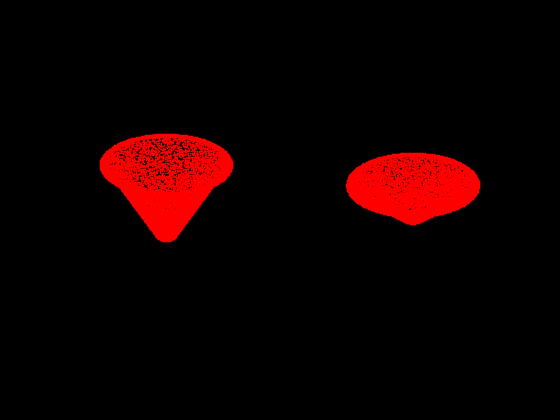

ptCld = pointCloud(pntcld,"Color","red");
ptCld2 = pointCloud(pntcld2,"Color","red");
figure
subplot(1,2,1);
pcshow(ptCld)
subplot(1,2,2);
pcshow(ptCld2)

### Spiral tool path for the pre-form (Z shifted) (Needed metrics)

pitch = 1; %mm/rev
res = 24; %planes/rev
dz = pitch/res;
dt = 360/res;
Z = 0:-1*dz:-1*abs(start_point(1))/tand(preform_angle);
t = 0;
X = zeros(size(Z)); Y = zeros(size(Z));
% sort the pointcloud2 by z-coordinates
pntcld2 = sortrows(pntcld2,3,"descend");
ptCld2 = pointCloud(pntcld2,"Color","red");
centre_pnt = [5 3 0];
notFound = 1;

% for each plane see the points that are nearest to the given angle
pt=1; 
for k= 1:size(Z,2)
    best_point = pntcld2(1,:);
    dif = Inf;
    % look at the points that are nearest to current angle
    for j = pt:size(pntcld2,1)
        if(pntcld2(j,3) > Z(k)-dz)
            angle = atan2d(pntcld2(j,2)-centre_pnt(2),pntcld2(j,1)-centre_pnt(1));
            if angle < 0
                angle = angle +360;
            end
            d = angle-t;
           if( d <=dif && d>=0)
               best_point = pntcld2(j,:);
               dif = d;
           end
        else
            pt = j;
            break;
        end
    end

    t = rem(t + dt,360);
    if((dif == Inf || dif > dt) && k>1)
        notFound = notFound +1;
        X(k) = X(k-1); Y(k) = Y(k-1); Z(k) = Z(k-1);
        continue;
    end
    X(k) = best_point(1); Y(k) = best_point(2); Z(k) = best_point(3);
    
    
end

success  = 100-notFound*100/size(Z,2);
disp([success "% points found"])

    "54.9327"    "% points found"



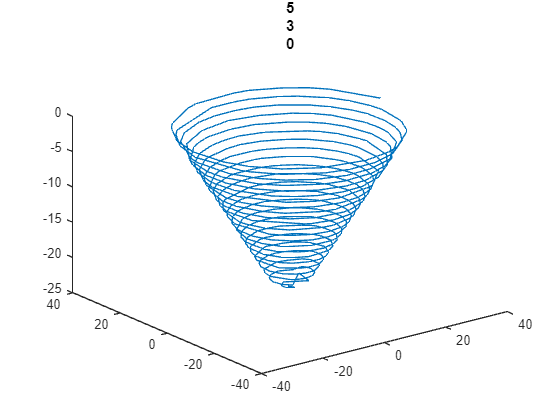


figure
plot3(X,Y,Z)
title(centre_pnt)

### Interpolation

%pts should be interpoloated in order

i = 1;
while i < 10
    i = i+2;
    disp(i)
end

     3

     5

     7

     9

    11



### Method-2 :  Normal shift (abandoned for now)

function [x,y,z] = normal_shift(point,start_point,preform_angle)
    r = norm(start_point(1:2));
    h = r*tan(preform_angle*pi/180);
    k = r/norm(point(1:2));
    a = k*point(1)/norm([h r]);   b = k*point(2)/norm([h r]);  c = -1*h/norm([h r]);
    alpha = dot([a b c],point-start_point);
    x = start_point(1)+a*alpha;
    y = start_point(2)+b*alpha;
    z = start_point(3)+c*alpha;
end